# Can you get sunburn behind a window?

Julius Muschaweck, August 2, 2021

## The short answer is: 

Yes, you can, but a typical double pane window with no additional coatings acts like "SPF 8": It will take you eight times as long to get the same sunburn effect behind a window. 

In addition, many double pane windows today have a so-called "low-E" coating for improved thermal insulation. Typically, this is a very thin silver coating on the outer surface of the inner pane, which reduces heat loss through thermal radiation from the inner to the outer pane, while being nearly completely transparent in the visible range. Silver blocks UV radiation, and some companies claim "99% UV protection", which is good for furniture and carpets, too. Behind such windows, you will not get sunburn at all. (see e.g. [https://www.viridianglass.com/products/energy-efficiency/comfortplus](https://www.viridianglass.com/products/energy-efficiency/comfortplus) and [https://glassed.vitroglazings.com/topics/the-science-of-low-e-coatings](https://glassed.vitroglazings.com/topics/the-science-of-low-e-coatings))

A car windshield or window provides similar protection.

## The reasoning goes like this: 

- Sunburn is caused by mostly invisible ultraviolet radiation (wavelengths < 400 nm) absorbed by the lower layers of the skin, the erythema. The "UV Index" uses a standardized curve that tells us how sensitive the erythema is to different wavelengths, see [https://www.ies.org/definitions/erythemal-action-spectrum/.](https://www.ies.org/definitions/erythemal-action-spectrum/.)

- Sunlight contains certain amounts of this ultraviolet radiation. ASTM International (formerly, the American Society for Testing and Materials, now an international standardization organization) has published some variants of solar radiation. Most important for us is the "AM 1.5 Global Irradiance" spectrum: This is what we get at sea level, on a clear day, when the sun is at a close to 49° angle. See [https://www.pveducation.org/pvcdrom/appendices/standard-solar-spectra](https://www.pveducation.org/pvcdrom/appendices/standard-solar-spectra) and [https://www.nrel.gov/grid/solar-resource/spectra-am1.5.html](https://www.nrel.gov/grid/solar-resource/spectra-am1.5.html) for more information. The "1.5" means that at that solar zenith angle, the sunlight traverses 1.5 times the distance of air, as compared to directly from above.

- The window weakens the sunlight via two effects: On each glass-air-surface, about 4% of the light is reflected, or 8% per pane. More important is the wavelength dependent absorption of sunlight in the glass itself. Window glass may appear completely clear to you, but it's not -- it's just that the absorption The thicker the glass, the more absorption. The [Lambert-Beer law](https://en.wikipedia.org/wiki/Beer%E2%80%93Lambert_law) relates actual absorption to material properties, which are available at e.g. [https://refractiveindex.info/?shelf=3d&book=glass&page=soda-lime-clear.](https://refractiveindex.info/?shelf=3d&book=glass&page=soda-lime-clear.)

- Then, we put it all together: We multiply the AM 1.5 spectrum  from 280 nm to 400 nm with the erythemal action spectrum to get the sensitivity weighted UV spectrum of sunlight. Integrating this spectrum over wavelength gives us a baseline number. Then, we multiply this spectrum with the window transmission spectrum, and integrate again. The ratio between the former and the latter integral is the effective sun protection factor of the window.

- Low-E coatings do not change this reasoning so far: They just add another element of protection.

- Applying similar reasoning to the atmosphere's transmission and absorption, we find that the atmosphere provides us with an effective SPF of about 105. 

## The code

This code uses routines from JMO's Spectrum library for Matlab, freely available at [https://github.com/JuliusMuschaweck/JMO_Spectrum](https://github.com/JuliusMuschaweck/JMO_Spectrum)

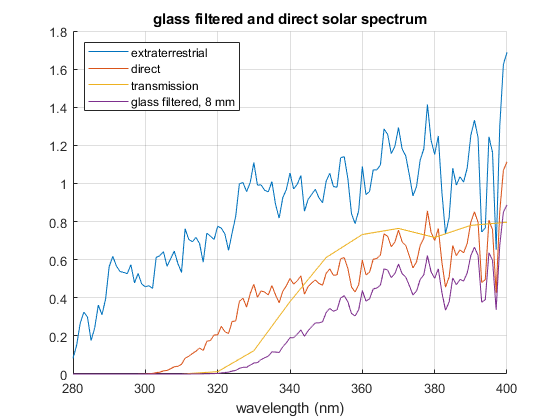

% obtain the solar spectra. In addition to AM 1.5 we also load the 
% extraterrestrial spectrum,
% to visualize the strong UV protection effect of the atmosphere.
clear;
am15 = SolarSpectrum('AM15_GlobalTilt');
am0 = SolarSpectrum('AM0');

% Take only the 280 .. 400 nm parts and plot them
UVs_AM15 = ResampleSpectrum(am15,280:400);
UVs_ext = ResampleSpectrum(am0,280:400);
figure();
clf;
hold on;
plot(UVs_ext.lam, UVs_ext.val);
plot(UVs_AM15.lam, UVs_AM15.val);

% soda lime glass transmission
% table from 
% https://refractiveindex.info/?shelf=3d&book=glass&page=soda-lime-clear
% extends only down to 310 nm, but we can safely set the 
% transmission to effectively zero below 310 nm 
% (1e-10 is effectively zero, but doesn't balk when we take the logarithm)
% from transmission at 4 mm...
tau_glass_4mm= MakeSpectrum( 280:10:400, [1e-10, 1e-10, 1e-10, 0.0003,...
    0.12, 0.38, 0.67, 0.85, 0.93, 0.95, 0.92, 0.96, 0.97]);
% we compute optical density according to Lambert-Beer
od_glass = MakeSpectrum(tau_glass_4mm.lam, - 0.25 * log10(tau_glass_4mm.val));

% typical window has two panes with 4 mm each
d_pane = 4;
n_pane = 2;
thickness = d_pane * n_pane;
% take partial reflection at glass-air interfaces into account
fresnel = 0.92^n_pane;
% now this is the overall transmission spectrum of our window
tau_glass = MakeSpectrum(od_glass.lam, fresnel *...
    10.^(- od_glass.val * thickness));

% shorthand for plot legends
ts = sprintf('glass filtered, %g mm',thickness);

% plot glass transmission and glass filtered AM 1.5 spectra
UV_filtered = MultiplySpectra(UVs_AM15, tau_glass);
plot(tau_glass.lam, tau_glass.val);
plot(UV_filtered.lam, UV_filtered.val);
grid on;
xlabel('wavelength (nm)');
title('glass filtered and direct solar spectrum');
legend({'extraterrestrial','direct','transmission',ts},...

    'Location','northwest');

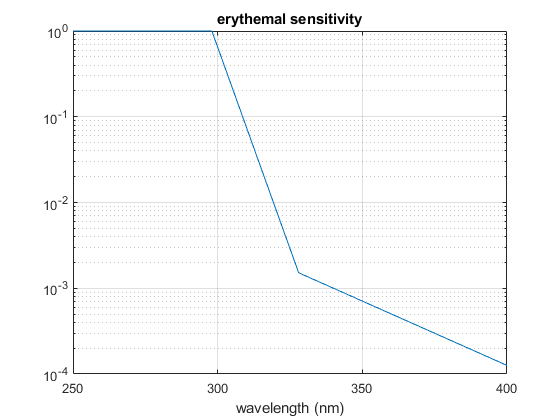

% The skin sensitivity

% https://www.ies.org/definitions/erythemal-action-spectrum/
ery.lam = 250:400;
ery.val = NaN(size(ery.lam));
for i = 1:length(ery.val)
    lam = ery.lam(i);
    if lam <= 298
        ery.val(i) = 1;
    elseif lam <= 328
        ery.val(i) = 10^(0.094 * (298-lam));
    else
        ery.val(i) = 10^(0.015 * (140-lam));
    end
end
figure();
semilogy(ery.lam, ery.val);
grid on;
xlabel('wavelength (nm)');
title('erythemal sensitivity');

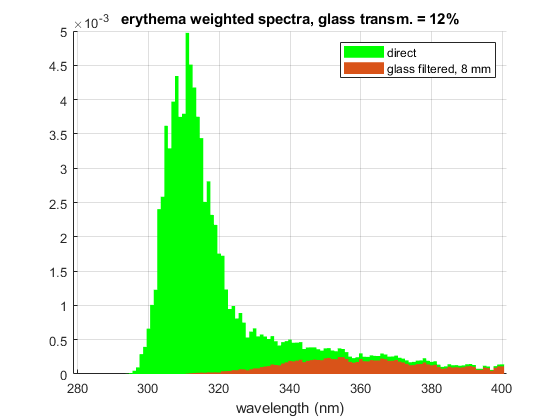





% compute and plot the erythema weighted spectra
figure();
clf; hold on;
grid on;
eff_UVs = MultiplySpectra(UVs_AM15, ery);
eff_filtered = MultiplySpectra(UV_filtered, ery);
bar(eff_UVs.lam, eff_UVs.val,1.0,'g','EdgeColor','none');
bar( eff_filtered.lam, eff_filtered.val,1.0,'EdgeColor','none');
sun_int = IntegrateSpectrum(eff_UVs);
filtered_int = IntegrateSpectrum(eff_filtered);
title(sprintf('erythema weighted spectra, glass transm. = %0.0f%%',...
    filtered_int / sun_int * 100));
xlabel('wavelength (nm)');
legend({'direct',ts});

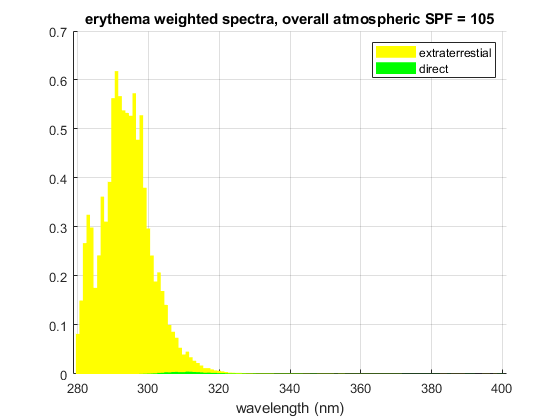








% compute and plot the erythema weighted extraterrestrial vs. AM1.5 spectra
figure();
clf; hold on;
grid on;
eff_UV_ext = MultiplySpectra(UVs_ext, ery);
eff_UVs = MultiplySpectra(UVs_AM15, ery);
bar(eff_UV_ext.lam, eff_UV_ext.val,1.0,'y','EdgeColor','none');
bar(eff_UVs.lam, eff_UVs.val,1.0,'g','EdgeColor','none');
extraterrestrial_int = IntegrateSpectrum(eff_UV_ext);
sun_int = IntegrateSpectrum(eff_UVs);
title(sprintf('erythema weighted spectra, overall atmospheric SPF = %0.0f',...
    extraterrestrial_int / sun_int));
xlabel('wavelength (nm)');
legend({'extraterrestial','direct'});